## E3 bis

#### Exercici 1

La lògica ens diu que integrar una imatge i després derivar-la ens deixaria la imatge original inalterada. Comproveu si és així al utilitzar dues finestres de convolució, una de integrativa i un altre de derivativa. I a l’inrevés?

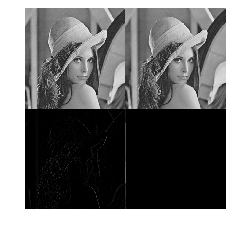

% 1r integral i 2n derivada
I = double(imread('lena_gray_512.tif'))/255;
h = ones([1 2])/2;
J = imfilter(I,h);
h1 = [1 -1];
K = imfilter(J,h1);
montage({I,J,K})

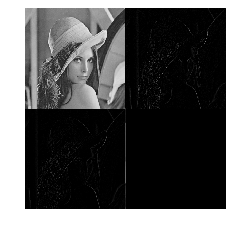


% 1r derivada i 2n integral
I = double(imread('lena_gray_512.tif'))/255;
h = [1 -1];
J = imfilter(I,h);
h1 = ones([1 2])/2;;
K = imfilter(J,h1);
montage({I,J,K})

#### Exercici 2

Enaltiu (*contour enhancement*) els contorns d’una imatge RGB. El resultat haurà de ser una imatge en nivells de gris combinant els tres canals.

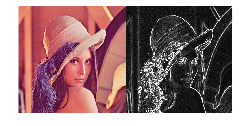

I = imread('lena_color_512.tif');

hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

Grx = abs(imfilter(double(R),hx));
Grx = Grx/max(max(Grx));
Gry = abs(imfilter(double(R),hy));
Gry = Gry/max(max(Gry));

Ggx = abs(imfilter(double(G),hx));
Ggx = Ggx/max(max(Ggx));
Ggy = abs(imfilter(double(G),hy));
Ggy = Ggy/max(max(Ggy));

Gbx = abs(imfilter(double(B),hx));
Gbx = Gbx/max(max(Gbx));
Gby = abs(imfilter(double(B),hy));
Gby = Gby/max(max(Gby));

Ig = Grx + Gry + Ggx + Ggy + Gbx + Gby;

montage({I,Ig});

#### Exercici 3

Quant una part de la imatge està desenfocada presenta els contorns borrosos o suavitzats. En base a aquest fet, fer una funció que mesuri un possible valor l’enfoc en la part central d’una imatge. Així, amb aquesta funció podrem decidir si una imatge està més ben enfocada que una altra (sistema d’auto-focus). Proveu amb dues imatges extretes d’internet (cerqueu les paraules clau  *focus stacking*)

I = imread('mosca_enfocada.jpg');
J = imread('mosca_desenfocada.jpg');

Is = myfunction4(I);
Js = myfunction4(J);
Is  % valor que indica l'enfocament al centre

Is = 35150100

Js  % ""

Js = 21013512

#### Exercici 4

Suavitzar una imatge per després redimensionar-la a la meitat dona un millor aspecte visual que directament redimensionar-la a la meitat. Mesureu si la relació senyal soroll millora al fer aquest procés comparant amb el de directament redimensionat sense filtrar. Per fer-ho, torneu les imatges processades a la seva mida original i calculeu el SNR.

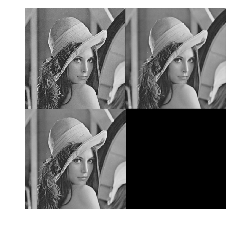

I = imread('lena_gray_512.tif');
h = fspecial("gaussian",5,0.8);
J = imfilter(I,h);

J = imresize(J,0.5);
K = imresize(I,0.5);

K = imresize(K,2);
J = imresize(J,2);
montage({I,J,K}) % I original, J amb filtre gaussià, K redimensionat sense filtrar


is = sum(sum(I.*I));
d = double(I) - double(K);
ds = sum(sum(d.*d));
SNR1 = is/ds   % relació senyal soroll entre original i redimensionat sense filtrar

SNR1 = 10.1052


is = sum(sum(I.*I));
d = double(I) - double(J);
ds = sum(sum(d.*d));
SNR2 = is/ds  % relació senyal soroll entre original i redimensionat amb filtre gaussià

SNR2 = 5.9190

### Funció exercici 3

function [Out] = myfunction4(I)
hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

Grx = abs(imfilter(double(R),hx));
% Grx = Grx/max(max(Grx));
Gry = abs(imfilter(double(R),hy));
% Gry = Gry/max(max(Gry));

Ggx = abs(imfilter(double(G),hx));
% Ggx = Ggx/max(max(Ggx));
Ggy = abs(imfilter(double(G),hy));
% Ggy = Ggy/max(max(Ggy));

Gbx = abs(imfilter(double(B),hx));
% Gbx = Gbx/max(max(Gbx));
Gby = abs(imfilter(double(B),hy));
% Gby = Gby/max(max(Gby));

Mg = Grx + Gry + Ggx + Ggy + Gbx + Gby;
% Out = Mg;
[files columnes] = size(Mg);
mf = floor(files/3);
mc = floor(columnes/3);
C = Mg(mf:end-mf, mc:end-mc);
s = sum(sum(C));
Out = s;
end